# **TU: Logistic Regression**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

### Binary linear classifier

`Method 1:`fitclinear()

- For two-class (binary) learning with **high-dimensional**, full or sparse predictor data. 

`Method 2:`fitglm()

- For low- through medium-dimensional predictor data sets, see [Alternatives for Lower-Dimensional Data](https://www.mathworks.com/help/releases/R2021b/stats/fitclinear.html#mw_d1b0a02e-0dfa-4c0e-bb4d-e6859309ec45)

# Examples

## **Example 1: Logistic Regression**

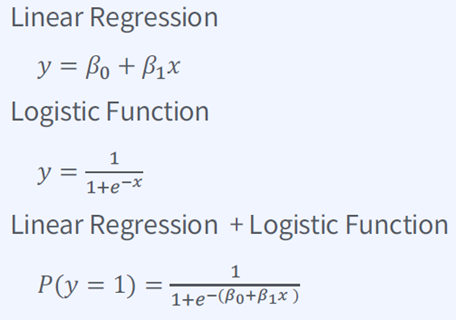

### **Data Acquisition** 

clear
load fisheriris
X = meas(:,1:2);            % Use two features (x1, x2) for fitting
sp = categorical(species);
Ystat=sp=='setosa';         % Binary classfication:  setosa vs no-setosa


### **Classification: **Logistic Regression 

Mdl = fitclinear(X,Ystat,'Learner','logistic')

Mdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [2×1 double]
              Bias: 8.3233
            Lambda: 0.0067
           Learner: 'logistic'


  Properties, Methods


**Plot**  Logistic Regression of Train data

- z= b0+b1X1+b2X2

- y=1/(1+exp(-z)) = h(z)

% Plot z vs Y=sigmoid(z)

z=Mdl.Bias+X*Mdl.Beta;

% Define logistif function h(z)=y
%%% YOUR CODE GOES HERE
a = exp(-z);
Y=1./(1+exp(-z));  

% Index of data which is class setosa
Y1indx=find(sp=='setosa')

Y1indx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


% Index of data which is NOT in class setosa
Y0indx=find(sp~='setosa')

Y0indx =     51
    52
    53
    54
    55
    56
    57
    58
    59
    60


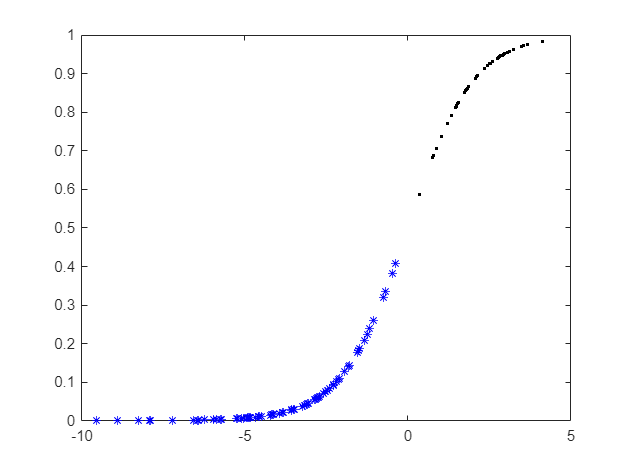

figure
plot(z(Y1indx),Y(Y1indx),'k.')
hold on
plot(z(Y0indx),Y(Y0indx),'b*')
hold off

### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

cvMdl = fitclinear(X,Ystat,'Learner','logistic', 'KFold',5)

cvMdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [0 1]
         ScoreTransform: 'none'


  Properties, Methods


Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

kloss = kfoldLoss(cvMdl)

kloss = 0

Get the optimal paramter of theta from the training

b0, b1, b2 of   z= b0+b1X1+b2X2

% b_0
Mdl.Bias

ans = 8.3233

% b_1, b_2
Mdl.Beta

ans =    -3.3883
    3.1645


### **Test **  

% an average flower feature values
flwr = mean(X); 
flwr2 = mean(X(1:10,:)); 
Xtest=flwr2;

% Convert TestData as Logistic Function
ztest=Mdl.Bias+Xtest*Mdl.Beta;
Ytest=1./(1+exp(-ztest))

Ytest = 0.9114

%%% YOUR CODE GOES HERE
flwrClass = predict(Mdl,Xtest)

flwrClass = logical
   1


# Exercise

## Exercise 1

Create a simple training of the logistic regression model using gradient descent. 

**Cost function**

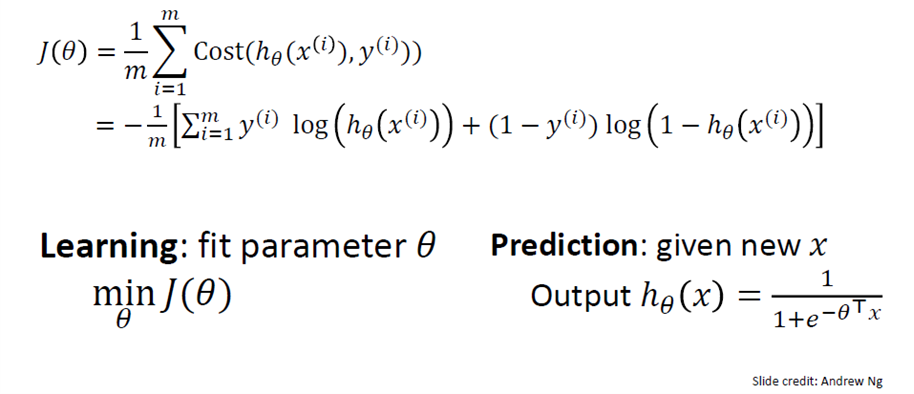

**Gradient Descent**

 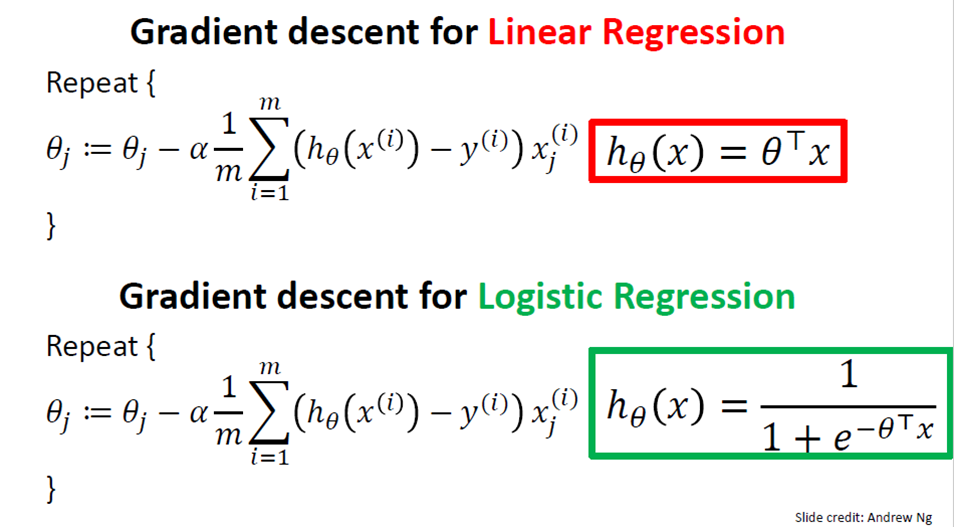

load fisheriris
X = meas(:,1:2);                % Use two features (x1, x2) for fitting
sp = categorical(species);
Y=double(sp=='setosa');         % Binary classfication:  setosa vs no-setosa
N=length(Y);

% Initialization of training
w1 = [-3, 3];
w0 = 8;
lamda=0.1;                      % learning rate
loss=1;
itrN=5000;
k=1;
while(loss>0.001 && k<itrN)
    
    % Define function h(x)
    h=1./(1+exp(-z));

    % Define gradient w.r.t theta_1 and theta_0
    dJt1 = -sum(h.*(Y));
    % dJt0 = ;

    % Update w1, w0
    % w1 =_____________;
    % w0 =_____________;
    
    % Cost Function
    loss = abs( (1/N)*sum(Y.*log(h) + (1-Y).*log(1-h)) );
    loss_hist(k) = loss;
    k = k+1;
end


Get the optimal paramter of theta from the training

b0, b1, b2 of   z= b0+b1X1+b2X2

% b_0
w0

w0 = 8

% b_1, b_2
w1

w1 =     -3     3


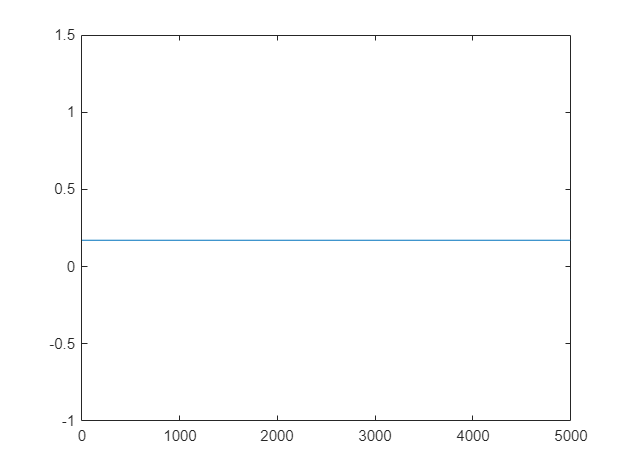


% Plot loss vs iteration
figure
plot(loss_hist) 

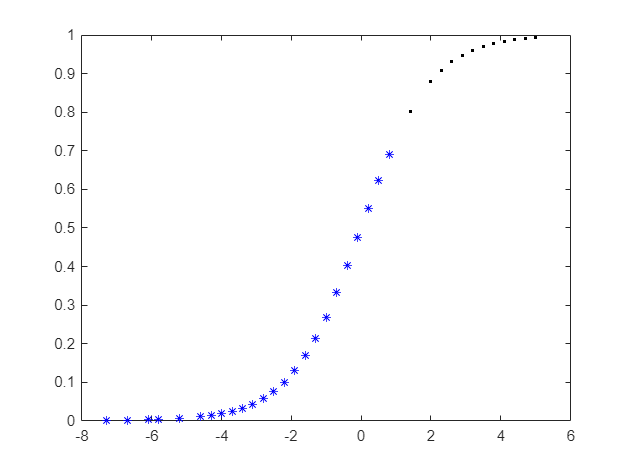


% Define z from (x, optimal w1 and w0)
z = X*w1' + w0;
% Calculate predicted Y from (x, optimal w1 and w0)
Y=1./(1+exp(-z));


% Index of data which is class setosa
Y1indx=find(sp=='setosa');
% Index of data which is NOT in class setosa
Y0indx=find(sp~='setosa');


% Plot the prediction output
figure
plot(z(Y1indx),Y(Y1indx),'k.') % class 1
hold on
plot(z(Y0indx),Y(Y0indx),'b*') % class 0
hold off

## Exercise 2:  CWRU dataset

Apply logistic regression to classifiy   outer or  inner bearing fault  

### Dataset 

- Given dataset contains many features extracted from CWRU dataset

- For binary class:  Class_Outer, Class_Inner  Race Fault

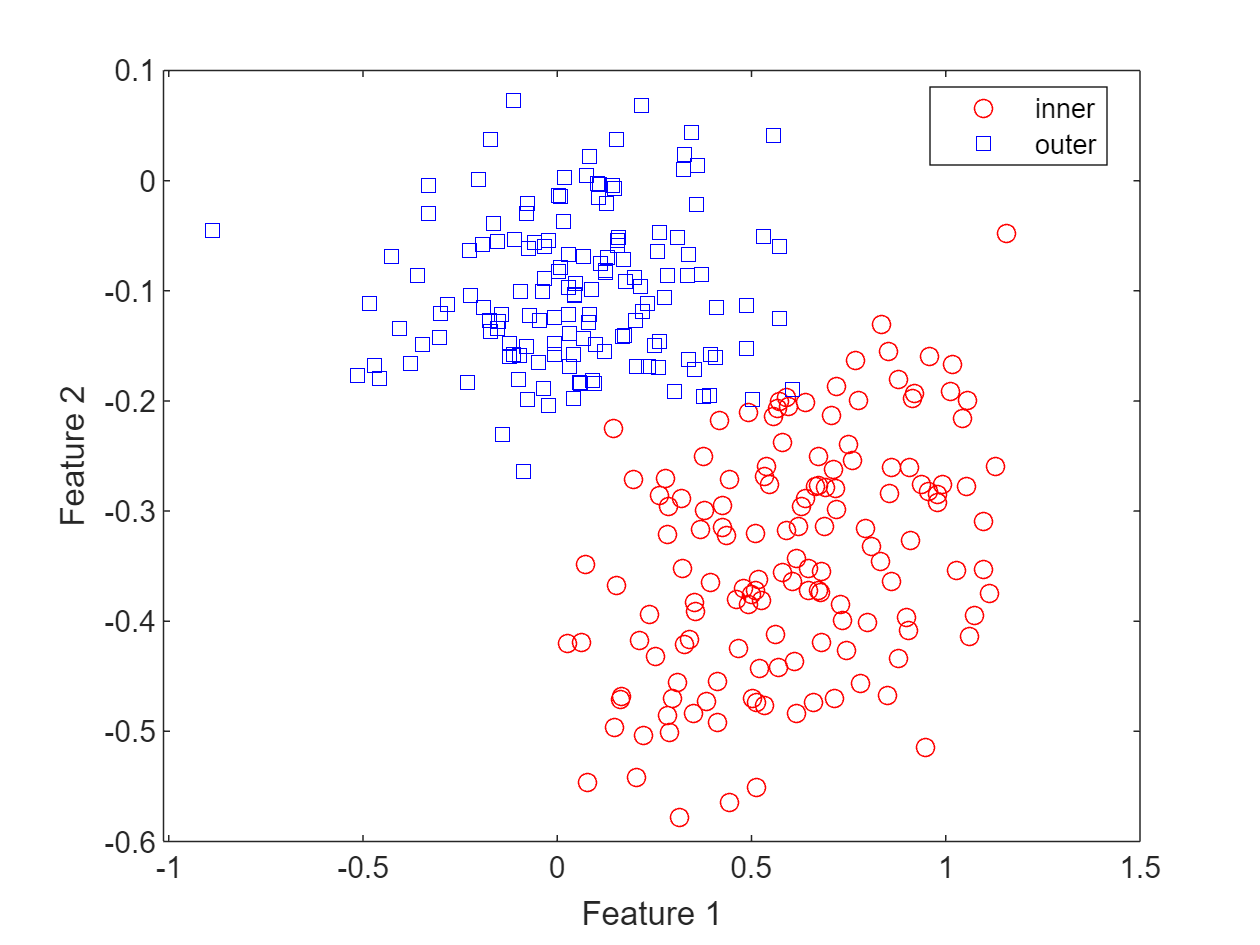

clear

% Load class 'Inner', 'Outer' dataset
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");
feature1 = "sv";                % skewness feature
feature2 = "ipf";               % impulse factor feature

% Prepare X, Y for train
Xtrain = [glob_all_train.(feature1), glob_all_train.(feature2)];
Ytrain = class_cwru_train;              % fault class label

% we want to keep only inner and outer race faults
% eliminate class normal. 
classKeep = ~strcmp(Ytrain,'normal');   
X = Xtrain(classKeep,:);
Y = Ytrain(classKeep);

% Plot features 
f = figure;
gscatter(X(:,1), X(:,2), Y,'rb','os');
xlabel('Feature 1');
ylabel('Feature 2');

### **Classify using Logistic Regression and Analyze **

% Use k-fold 5 for logistic regression fit
Y = categorical(Y);

% Your code goes here
% Mdl = fitclinear(_______________);

Mdl =   ClassificationPartitionedLinear
    CrossValidatedModel: 'Linear'
           ResponseName: 'Y'
        NumObservations: 288
                  KFold: 5
              Partition: [1×1 cvpartition]
             ClassNames: [inner    outer]
         ScoreTransform: 'none'


  Properties, Methods



kfoldloss = kfoldLoss(Mdl)

kfoldloss = 0.0590

### **Predict  test data and Analyze**

% Load Class 'Inner', 'Outer'
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");

% Prepare X, Y for test
% Your code goes here
Xtest = [glob_all_test.(feature1), glob_all_test.(feature2)];
Ytest = class_cwru_test;

% we want to keep only inner and outer race faults
% eliminate class normal. 
classKeep_test = ~strcmp(Ytest,'normal');
Xtest = Xtest(classKeep_test, :);
Ytest = Ytest(classKeep_test);

% Display Loss value
% loss = ___________

loss = 0.0278

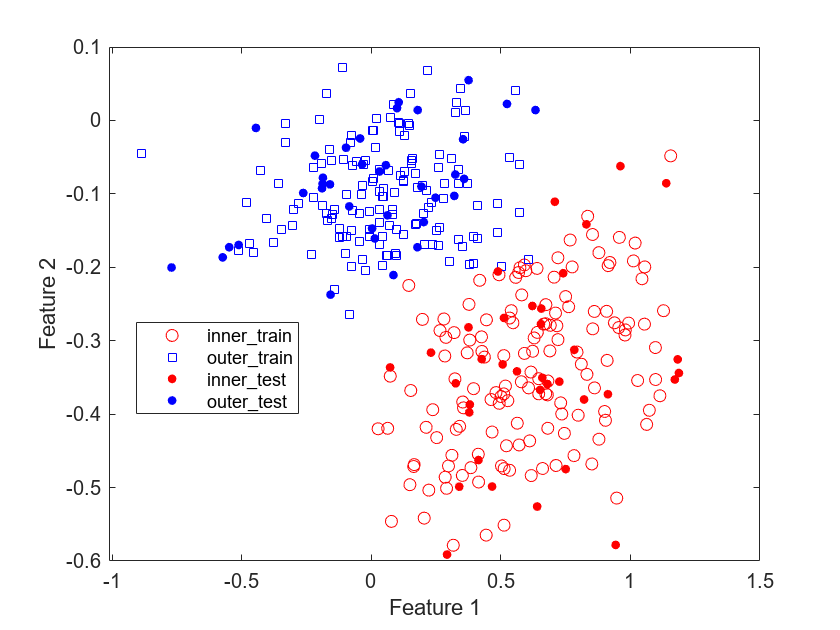


% Plot the prediction 
figure
gscatter(X(:,1), X(:,2), Y,'rb','os'); hold on;
gscatter(Xtest(:,1), Xtest(:,2), Ytest, 'rb', '..')
xlabel('Feature 1');
ylabel('Feature 2');
legend('inner\_train', 'outer\_train', 'inner\_test', 'outer\_test');